# Creat Grid Map

`@author: Winter`

`@update: 2023.1.29`

## function import

addpath(genpath("env\"));
addpath(genpath("Users/jonas/Desktop/Studie/h25/IN5060/matlab_motion_planning/utils/env\"));

## map A

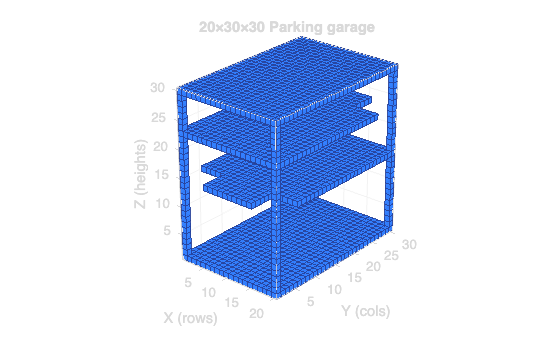

% main.m
clear; clc; close all;

% Map settings: [rows, cols, heights]
map_size = [20, 30, 30];
rows = map_size(1); cols = map_size(2); heights = map_size(3);

% Corner numbering (viewed in matrix/plot coordinates):
% 1: top-left     (row=1,   col=1)
% 2: top-right    (row=1,   col=cols)
% 3: bottom-left  (row=rows,col=1)
% 4: bottom-right (row=rows,col=cols)

holeSize = 5;                        % 5x5 holes
hR = min(holeSize, rows);
hC = min(holeSize, cols);

obstacle = [];

%% 1) Ground floor (full slab at z = 1)
[Rf,Cf,Zf] = ndgrid(1:rows, 1:cols, 1);
obstacle = [obstacle; sub2ind(map_size, Rf(:), Cf(:), Zf(:))];

%% 2) Corner columns (all heights at the four corners)
rC = [1, rows];
cC = [1, cols];
zC = 1:heights;
[RC, CC, ZC] = ndgrid(rC, cC, zC);
obstacle = [obstacle; sub2ind(map_size, RC(:), CC(:), ZC(:))];

%% 3) Middle floor (full slab) with 5x5 holes in corners 1 & 3
z_mid = round(heights/2);
[Rm,Cm,Zm] = ndgrid(1:rows, 1:cols, z_mid);
slab_mid = sub2ind(map_size, Rm(:), Cm(:), Zm(:));

holes_mid = [
    corner_hole_idx(1, z_mid, rows, cols, hR, hC, map_size);
    corner_hole_idx(3, z_mid, rows, cols, hR, hC, map_size)
];
slab_mid = setdiff(slab_mid, holes_mid);
obstacle = [obstacle; slab_mid];

%% 3b) Upper floor (full slab) with 5x5 holes in corners 2 & 4
z_upper = round(heights*3/4);
[Ru,Cu,Zu] = ndgrid(1:rows, 1:cols, z_upper);
slab_up = sub2ind(map_size, Ru(:), Cu(:), Zu(:));

holes_up = [
    corner_hole_idx(2, z_upper, rows, cols, hR, hC, map_size);
    corner_hole_idx(4, z_upper, rows, cols, hR, hC, map_size)
];
slab_up = setdiff(slab_up, holes_up);
obstacle = [obstacle; slab_up];

%% 4) Roof (full slab at top z)
[Rr,Cr,Zr] = ndgrid(1:rows, 1:cols, heights);
obstacle = [obstacle; sub2ind(map_size, Rr(:), Cr(:), Zr(:))];

%% Finalize & plot
obstacle = unique(obstacle);
grid_map = generate_grid(map_size, obstacle);
save('gridmap_20x30x30_garage_5x5_alt_holes.mat','grid_map');
plot_grid_3d(grid_map);


% ---------- helpers ----------
function idx = corner_hole_idx(corner, z, rows, cols, hR, hC, map_size)
% Return linear indices for a hR-by-hC hole at a given corner & height z.
    switch corner
        case 1  % top-left
            r = 1:hR;        c = 1:hC;
        case 2  % top-right
            r = 1:hR;        c = (cols-hC+1):cols;
        case 3  % bottom-left
            r = (rows-hR+1):rows;  c = 1:hC;
        case 4  % bottom-right
            r = (rows-hR+1):rows;  c = (cols-hC+1):cols;
        otherwise
            error('corner must be 1..4');
    end
    [R,C,Z] = ndgrid(r, c, z);
    idx = sub2ind(map_size, R(:), C(:), Z(:));
end






## map B

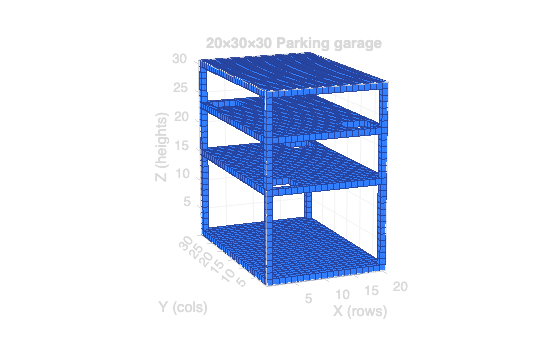

% main.m
clear; clc; close all;

% Map settings: [rows, cols, heights]
map_size = [20, 30, 30];
rows = map_size(1); cols = map_size(2); heights = map_size(3);

% Corner numbering (matrix view):
% 1: top-left, 2: top-right, 3: bottom-left, 4: bottom-right

holeSize = 5;           % 5x5 holes
offsetFromCorner = 1;   % keep holes 1 cell away from the columns (set 0 to include corner cell)

% Adjust hole span if offset reduces available space
hR = min(holeSize, rows - 2*offsetFromCorner);
hC = min(holeSize, cols - 2*offsetFromCorner);

obstacle = [];

%% 1) Ground floor (full slab at z=1)
[Rf,Cf,Zf] = ndgrid(1:rows, 1:cols, 1);
obstacle = [obstacle; sub2ind(map_size, Rf(:), Cf(:), Zf(:))];

%% 2) Corner columns (all heights at the four corners)
rC = [1, rows]; cC = [1, cols]; zC = 1:heights;
[RC, CC, ZC] = ndgrid(rC, cC, zC);
obstacle = [obstacle; sub2ind(map_size, RC(:), CC(:), ZC(:))];

%% 3) Middle floor (z_mid) with 5x5 holes in corners 1 & 4 (diagonal)
z_mid = round(heights/2);
[Rm,Cm,Zm] = ndgrid(1:rows, 1:cols, z_mid);
slab_mid = sub2ind(map_size, Rm(:), Cm(:), Zm(:));

holes_mid = [
    corner_hole_idx_2(1, z_mid, rows, cols, hR, hC, map_size, offsetFromCorner);
    corner_hole_idx_2(4, z_mid, rows, cols, hR, hC, map_size, offsetFromCorner)
];
slab_mid = setdiff(slab_mid, holes_mid);
obstacle = [obstacle; slab_mid];

%% 3b) Upper floor (z_upper) with 5x5 holes in corners 2 & 3 (other diagonal)
z_upper = round(heights*3/4);
[Ru,Cu,Zu] = ndgrid(1:rows, 1:cols, z_upper);
slab_up = sub2ind(map_size, Ru(:), Cu(:), Zu(:));

holes_up = [
    corner_hole_idx_2(2, z_upper, rows, cols, hR, hC, map_size, offsetFromCorner);
    corner_hole_idx_2(3, z_upper, rows, cols, hR, hC, map_size, offsetFromCorner)
];
slab_up = setdiff(slab_up, holes_up);
obstacle = [obstacle; slab_up];

%% 4) Roof (full slab at top)
[Rr,Cr,Zr] = ndgrid(1:rows, 1:cols, heights);
obstacle = [obstacle; sub2ind(map_size, Rr(:), Cr(:), Zr(:))];

%% Build & plot
obstacle = unique(obstacle);
grid_map = generate_grid(map_size, obstacle);
save('gridmap_20x30x30_garage_5x5_diag_holes.mat','grid_map');
plot_grid_3d(grid_map);


function idx = corner_hole_idx_2(corner, z, rows, cols, hR, hC, map_size, off)
% Return linear indices for a hR-by-hC rectangular hole at a given corner & z,
% offset 'off' cells from each wall so corner columns remain.
    switch corner
        case 1 % top-left
            r = (1+off):(hR+off);
            c = (1+off):(hC+off);
        case 2 % top-right
            r = (1+off):(hR+off);
            c = (cols-hC-off+1):(cols-off);
        case 3 % bottom-left
            r = (rows-hR-off+1):(rows-off);
            c = (1+off):(hC+off);
        case 4 % bottom-right
            r = (rows-hR-off+1):(rows-off);
            c = (cols-hC-off+1):(cols-off);
        otherwise
            error('corner must be 1..4');
    end
    % Clamp to bounds (in case size/offset leaves no room)
    r = max(1, min(rows, r));  c = max(1, min(cols, c));
    [R,C,Z] = ndgrid(r, c, z);
    idx = sub2ind(map_size, R(:), C(:), Z(:));
end



## map C

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1;    

% obstacle
obs1 = [56, 57, 58, 59, 60, 76, 77, 78, 79, 80];
obs2 = [241, 242, 243, 244, 245, 246, 247, 248, 249, 250, 251, 252, 253, 254, 255, 256, 257, 258];
obs3 = [128, 129, 130, 131, 132, 152, 172, 192, 191, 190, 189, 188];
obs4 = [311, 312, 313, 314, 315, 316, 317, 318, 319, 320];
obs5 = [138, 158, 178, 198, 218, 238, 175, 195, 215, 235, 255];
obs6 = [124, 144, 164, 184, 143, 163, 145, 165];
obs7 = [267, 287, 307, 327, 347, 321, 322, 323, 324];
obs8 = [370, 390, 371, 391, 334, 354, 335, 354, 355, 378, 398];
obstacle = [obs1, obs1- 8, obs1 - 15, obs2, obs3, obs4, obs5, obs6, obs7, obs8];
    
% creat grid
grid_map = generate_grid(map_size, obstacle);

Error using generate_grid (line 14)
Invalid argument at position 1. Value must be a vector with 3 elements.


% save and plot
% save gridmap_20x20_scene3 grid_map
plot_grid(grid_map);

## map D

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1; 

% obstacle
obs1 = 81:88;
obs2 = 90:100;
obs3 = 270:277;
obs4 = [290, 310, 350, 370, 390];

obstacle = [obs1, obs2, obs1 + 20, obs2 + 20, obs1 + 40, obs2 + 40, obs1 + 60, obs2 + 60, obs1 + 80, obs2 + 80, ...
    obs1 + 100, obs2 + 100, obs3, obs4];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene4 grid_map
plot_grid(grid_map);

## map E

clear all;
clc;

% map setting
map_size = [20, 30, 30];
G = 1;

% obstacle
obs0 = [1:map_size(1), ... 
        map_size(1):map_size(1):map_size(1) * map_size(2), ...
        1:map_size(1):(map_size(1) - 1) * map_size(2), ...
        map_size(1) * (map_size(2) - 1):map_size(1) * map_size(2)];
obs1 = [63, 83, 103, 123, 143, 163, 183, 203, 223, 243, 263, 124, 125, 126, 127];
obs2 = [46, 47, 48, 49, 50, 70, 90, 110, 130, 150, 170, 190, 210, 230, 250, 270, 269];
obs3 = [73, 74, 55, 75, 95, 56, 76, 96, 77, 78];
obs4 = [253, 254, 235, 255, 275, 236, 256, 276, 257, 258];
obs5 = [352, 372, 392, 412, 432, 452, 472, 492, 512, 532];
obs6 = [435, 416, 436, 417, 437, 438, 455, 456, 476, 457, 477, 458];
obs7 = [363, 364, 365, 366, 367, 383, 403];
obs8 = [446, 447, 448, 449, 466, 467, 468, 469];
obstacle = [obs0, obs1, obs2, obs3, obs4, obs5, obs6, obs7, obs8];




% creat grid
grid_map = generate_grid(map_size, obstacle); 

% save and plot
save gridmap_20x20_scene1 grid_map
plot_grid(grid_map);



clear all;
clc;

% map setting
map_size = [20, 20];
G = 1; 

% obstacle
obs = [62, 63, 82, 83];
obstacle = [];
for i=0:5
    for j=0:5
        obs_ = obs + 60 * i + 3 * j;
        obstacle = [obstacle, obs_];
    end
end
% obstacle = [obs, obs + 60];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene4 grid_map
plot_grid(grid_map);